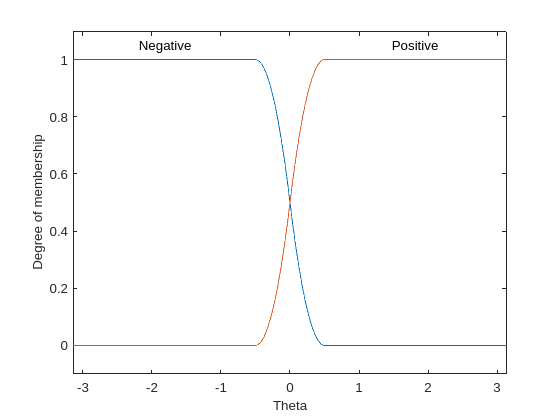

% Cart/Pole Fuzzy Inference System

cartpole2FIS = mamfis(...
    'NumInputs',2,'NumInputMFs',2,...
    'NumOutputs',1,'NumOutputMFs',4,...
    'AddRule','none');

%Inputs
cartpole2FIS.Inputs(1).Name = 'Theta';
cartpole2FIS.Inputs(1).Range = [-pi pi];
cartpole2FIS.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cartpole2FIS.Inputs(1).MembershipFunctions(1).Type = 'zmf';
cartpole2FIS.Inputs(1).MembershipFunctions(1).Parameters = [-0.5 0.5];
cartpole2FIS.Inputs(1).MembershipFunctions(2).Name = 'Positive';
cartpole2FIS.Inputs(1).MembershipFunctions(2).Type = 'smf';
cartpole2FIS.Inputs(1).MembershipFunctions(2).Parameters = [-0.5 0.5];

cartpole2FIS.Inputs(2).Name = 'Theta_dot';
cartpole2FIS.Inputs(2).Range = [-5 5];
cartpole2FIS.Inputs(2).MembershipFunctions(1).Name = 'Negative';
cartpole2FIS.Inputs(2).MembershipFunctions(1).Type = 'zmf';
cartpole2FIS.Inputs(2).MembershipFunctions(1).Parameters = [-5 5];
cartpole2FIS.Inputs(2).MembershipFunctions(2).Name = 'Positive';
cartpole2FIS.Inputs(2).MembershipFunctions(2).Type = 'smf';
cartpole2FIS.Inputs(2).MembershipFunctions(2).Parameters = [-5 5];

plotmf(cartpole2FIS,'input',1,1000);

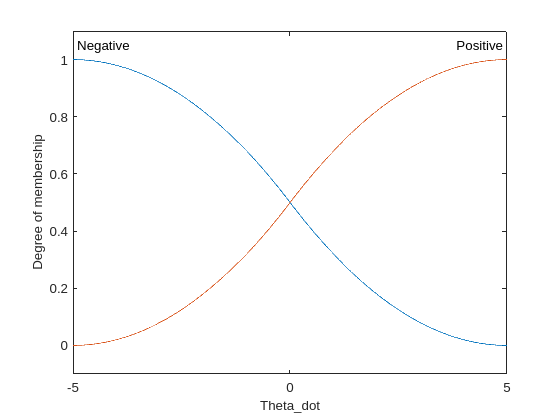

plotmf(cartpole2FIS,'input',2,1000);

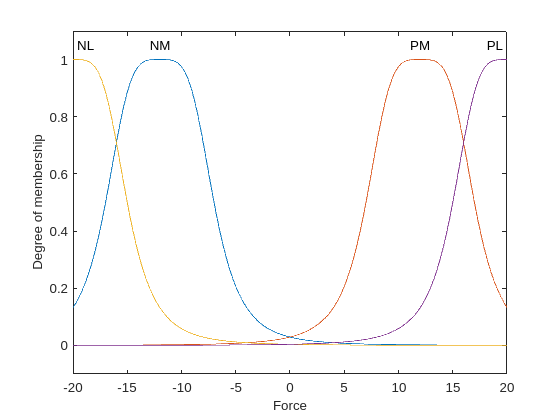

%Outputs
cartpole2FIS.Outputs(1).Name = 'Force';
cartpole2FIS.Outputs(1).Range = [-20 20];
cartpole2FIS.Outputs(1).MembershipFunctions(1).Name = 'NM';%Negative Medium
cartpole2FIS.Outputs(1).MembershipFunctions(1).Type = 'gbellmf';
cartpole2FIS.Outputs(1).MembershipFunctions(1).Parameters = [5 2 -12];
cartpole2FIS.Outputs(1).MembershipFunctions(2).Name = 'PM';%Positive Medium
cartpole2FIS.Outputs(1).MembershipFunctions(2).Type = 'gbellmf';
cartpole2FIS.Outputs(1).MembershipFunctions(2).Parameters = [5 2 12];
cartpole2FIS.Outputs(1).MembershipFunctions(3).Name = 'NL';%Negative Large
cartpole2FIS.Outputs(1).MembershipFunctions(3).Type = 'gbellmf';
cartpole2FIS.Outputs(1).MembershipFunctions(3).Parameters = [5 2 -20];
cartpole2FIS.Outputs(1).MembershipFunctions(4).Name = 'PL';%Positive Large
cartpole2FIS.Outputs(1).MembershipFunctions(4).Type = 'gbellmf';
cartpole2FIS.Outputs(1).MembershipFunctions(4).Parameters = [5 2 20];

plotmf(cartpole2FIS,'output',1,1000);

%Specify Rules
rules = [...
    "If Theta is Negative then Force is NM";...
    "If Theta is Positive then Force is PM";...
    "If Theta_dot is Negative then Force is NL";...
    "If Theta_dot is Positive then Force is PL"];

cartpole2FIS = addRule(cartpole2FIS,rules);